clear all, close all, clc
M350_F = importdata("29028 Shuttlecock_Synthetic_M350_Fixed_Coarse.dat");
M350_R = importdata("29029 Shuttlecock_Synthetic_M350_with_Spin_Coarse.dat");
M2000_F = importdata("29031 Shuttlecock_Synthetic_M2200_Fixed_Coarse.dat");
M2000_R = importdata("29030 Shuttlecock_Synthetic_M2200_with_Spin_Coarse.dat");
A50_F = importdata("29035 Shuttlecock_Feather_A50_Fixed_Coarse.dat");
% A50_R = importdata("29036 Shuttlecock_Feather_A50_with_Spin_Coarse.dat");
rovsT = readtable('rovsT.xlsx');


path = {'D:\IITK\Projects\Prof Mittal\New experiment\00_Shuttlecock_Aarush\Write\M350_tare without tare.csv', 'D:\IITK\Projects\Prof Mittal\New experiment\00_Shuttlecock_Aarush\Write\M2000_tare without tare.csv','D:\IITK\Projects\Prof Mittal\New experiment\00_Shuttlecock_Aarush\Write\A50_tare without tare.csv'};
M350_T  = readmatrix(path{1});
M2000_T  = readmatrix(path{2});
A50_T  = readmatrix(path{3});


%Adding row for resudual
for i = 1:7
    A50_F(i*9,:) = sqrt(A50_F((i-1)*9 + 4,:).^2 +  A50_F((i-1)*9 + 5,:).^2);
    %A50_R(i*9,:) = sqrt(A50_R((i-1)*9 + 4,:).^2 +  A50_R((i-1)*9 + 5,:).^2);
    M350_F(i*9,:) = sqrt(M350_F((i-1)*9 + 4,:).^2 +  M350_F((i-1)*9 + 5,:).^2);
    M350_R(i*9,:) = sqrt(M350_R((i-1)*9 + 4,:).^2 +  M350_R((i-1)*9 + 5,:).^2);
    M2000_F(i*9,:) = sqrt(M2000_F((i-1)*9 + 4,:).^2 +  M2000_F((i-1)*9 + 5,:).^2);
    M2000_R(i*9,:) = sqrt(M2000_R((i-1)*9 + 4,:).^2 +  M2000_R((i-1)*9 + 5,:).^2);
end

%creating column for velocity and reynold number 
M350_Fu=createU(M350_F);

M350_Ru=createU(M350_R);

M2000_Fu=createU(M2000_F);

M2000_Ru=createU(M2000_R);

A50_Fu=createU(A50_F);

%A50_Ru=createU(A50_R);


%tare correction
for i = 1:7
    for j = 1:7
        M350_F((i-1)*9 + 2 + j ,:) = M350_F((i-1)*9 + 2 + j,:) - interp1(M350_T(:,15),M350_T(:,5+j),M350_Fu(i,1),'linear','extrap');
        M350_R((i-1)*9 + 2 + j,:) = M350_R((i-1)*9 + 2 + j,:) - interp1(M350_T(:,15),M350_T(:,5+j),M350_Ru(i,1),'linear','extrap');
        M2000_F((i-1)*9 + 2 + j,:) = M2000_F((i-1)*9 + 2 + j,:)- interp1(M2000_T(:,15),M2000_T(:,5+j),M2000_Fu(i,1),'linear','extrap');
        M2000_R((i-1)*9 + 2 + j,:) = M2000_R((i-1)*9 + 2 + j,:)- interp1(M2000_T(:,15),M2000_T(:,5+j),M2000_Ru(i,1),'linear','extrap');
        A50_F((i-1)*9 + 2 + j,:) = A50_F((i-1)*9 + 2 + j,:)- interp1(A50_T(:,15),A50_T(:,5+j),A50_Fu(i,1),'linear','extrap');
        %A50_R((i-1)*9 + 2 + j,:) = A50_R((i-1)*9 + 2 + j,:)- interp1(A50_T(i,15),A50_T(i,5+j),A50_Ru(i,1),'linear','extrap');
    end
end


%finding mean 
M350_Fm = findm(M350_F);
M350_Rm = findm(M350_R);
M2000_Fm = findm(M2000_F);
M2000_Rm = findm(M2000_R);
A50_Fm = findm(A50_F);
% A50_Rm = findm(A50_R);

%peak arrays
M350_F_peaks = cell(7*7, 2);
M350_R_peaks = cell(7*7, 2);
M2000_F_peaks = cell(7*7, 2);
M2000_R_peaks = cell(7*7, 2);
A50_F_peaks = cell(7*7, 2);
A50_R_peaks = cell(7*7, 2);
col = {'Ax','S','N','Rm','Pm','Ym','Resu'};
col3 = {'10','20','30','40','50','60','70'};

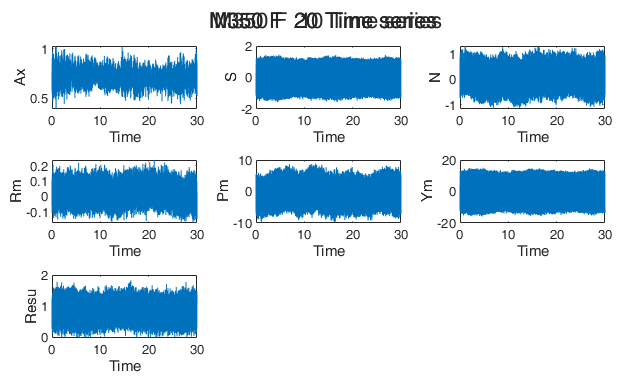

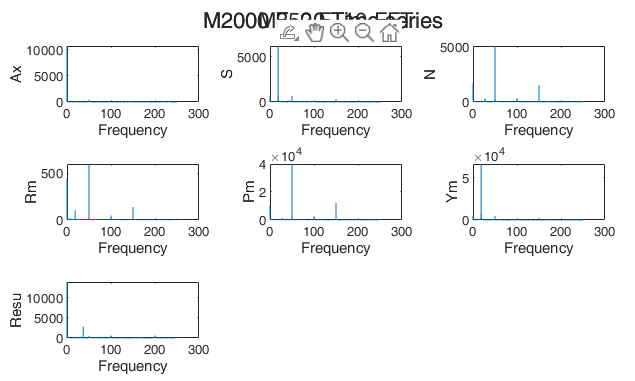

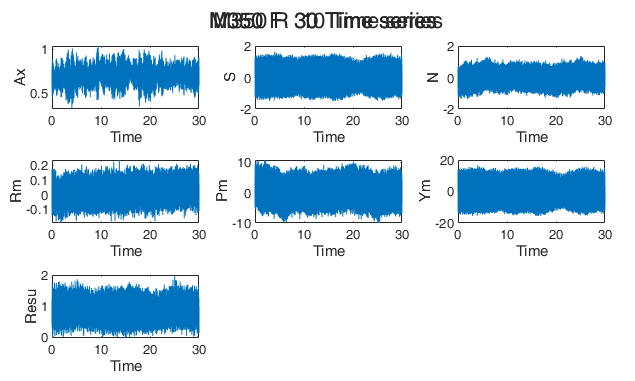

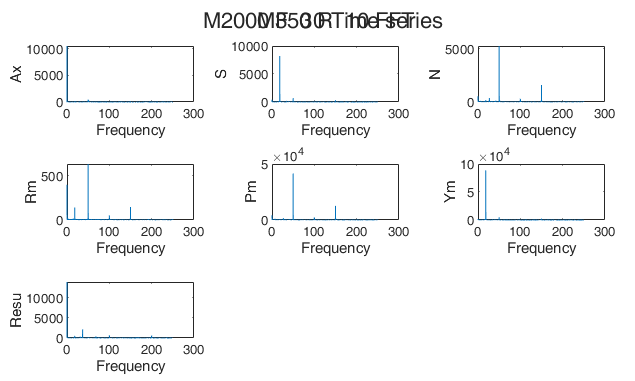

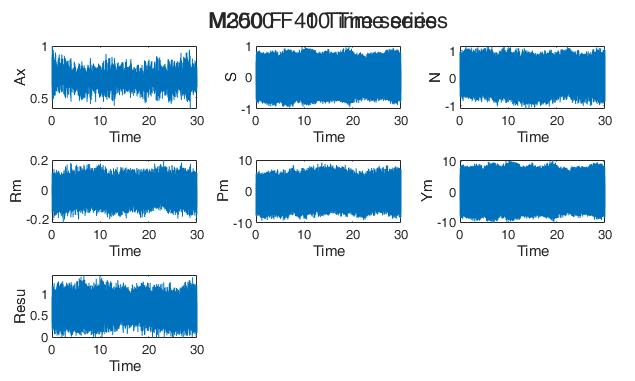

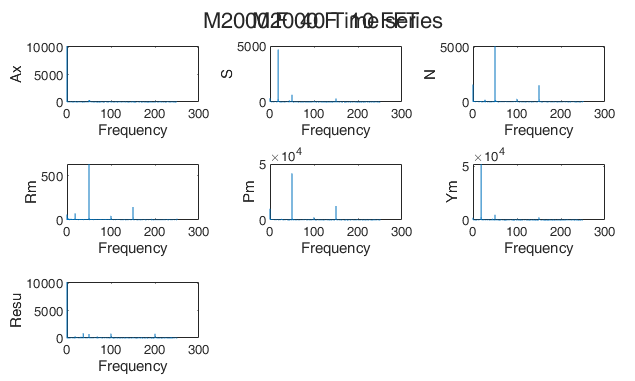

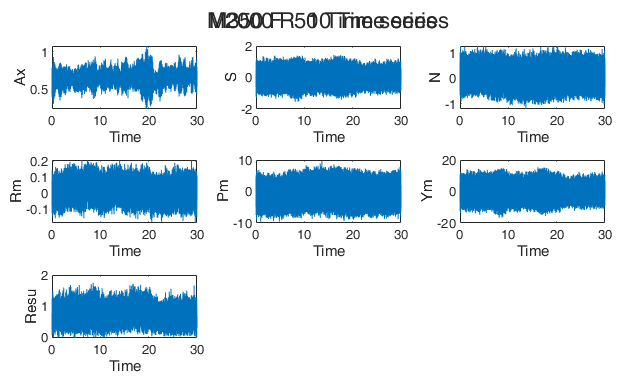

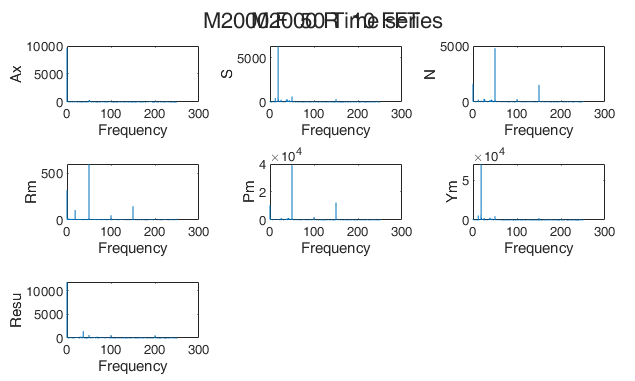

for i = 1:7
    M350_F_peaks = fftplotbal_all(M350_F((i-1)*9 + (3:9),:) ,col, "M350 F ",i ,500,M350_F_peaks);
    M350_R_peaks = fftplotbal_all(M350_R((i-1)*9 + (3:9),:),col, "M350 R ",i ,500,M350_R_peaks);
    M2000_F_peaks = fftplotbal_all(M2000_F((i-1)*9 + (3:9),:),col, "M2000 F ",i ,500,M2000_F_peaks);
    M2000_R_peaks = fftplotbal_all(M2000_R((i-1)*9 + (3:9),:),col, "M2000 R ",i ,500,M2000_R_peaks);
end

%- M2000_Rm(i,3:9).'

% peaks for cell 
M350_F_peaksa = zeros(7*7*2,10);
M350_R_peaksa = zeros(7*7*2,10);
M2000_F_peaksa = zeros(7*7*2,10);
M2000_R_peaksa = zeros(7*7*2,10);
A50_F_peaksa = zeros(7*7*2,10);
A50_R_peaksa = zeros(7*7*2,10);



for i = 1:size(M350_R_peaks,1)
    
    M350_F_peaksa((i-1)*2 + (1:2),:) = sortm(M350_F_peaks(i,:));
   

    M350_R_peaksa((i-1)*2 + (1:2),:) = sortm(M350_R_peaks(i,:));
 
    M2000_F_peaksa((i-1)*2 + (1:2),:) = sortm(M2000_F_peaks(i,:));
 
    M2000_R_peaksa((i-1)*2 + (1:2),:) = sortm(M2000_R_peaks(i,:));
   
    %A50_F_peaksa((i-1)*2 + (1:2),:) = sortm(A50_F_peaks(i,:));
 
    %A50_R_peaksa((i-1)*2 + (1:2),:) = sortm(A50_R_peaks(i,1));

end